 clc; clear;
%tube diameter 4cm
%use frequencies are [6,12,18,24], data_1 is with the fan off
R = 287; % J/kgK
P_infinity = 106.671*10^3; %(Pa) originally 30.02 in Hg
T = 295; % (Kelvin)
N = 15000;
d= 4/100;




% Converstion Variables:
%_____________________________________________________
Inch_water_col_to_pascal_conversion = 248.84;
kd = -27.3317 %pull these from the drag and lift coeff

kd = -27.3317

kl = 107.8661

kl = 107.8661


%dp dynamic pressure from previous labs
dp20 = 251.73 %pascal %1.01162 inh20

dp20 = 251.7300


dp10_error = 1.9145; %This is from the std from lab 2 
dp20_error = 1.9922;



% Basic Equations:
%_____________________________________________________
air_density = P_infinity/(R*T) % kg/m^3 from ideal gas law

air_density = 1.2599

velocity2 = 20;
dynamic_viscosity = 1.8e-5;


%-----------------------
%Record with the fan off to get a base line for 0

dir_address='C:\Users\kaleb\Downloads\DIY'; % paste the address of the folder your Cd data is saved within the ('')inverted commas

read_mat_files(dir_address)


% Load the data from the file
%{
file_path = 'C:\Users\nailsk\Downloads\AE lab 3\DragCalibCoeff.mat';
calibdata = load(file_path);

% Access the variables in the loaded data
kd = calibdata.pDrag(1) 
kd_error = 0
%}
%1st column is lift second column is drag

%Drag_Sting_10 = kd * (Sec2_drag_Sting_10 - Sec2_drag_Sting_10_tare);
%Drag_Sting_20 = kd * (Sec2_drag_Sting_20 - Sec2_drag_Sting_20_tare);

%DEFINE SOME IMPORTANT VARIABLES
%hard coded error from lab 3
error = 0.05*10^-3;
%calculate S, from image
S_wing =0.008773

S_wing = 0.0088

S_error = .005^2; %error of the area %SOMEONE DOUBLE CHECK THIS ERROR

%describe some wing terms
ew = .893; Aw = 11.238; 

%calculate charecteristic length which is length of the fuel salage
lf = .2413 %m

lf = 0.2413

%calculate your reynolds number
reynolds = (lf*20*air_density)/dynamic_viscosity

reynolds = 3.3780e+05


% Calculate the drag for each object
LD_neg3(:,1) = kl * (Sec2_LiftDrag_c130_neg3_20mps(:,1) - Sec2_LiftDrag_c130_neg3_20mps_tare(:,1) - (Sec2_LiftDrag_c130_sting_20mps(:,1) - Sec2_LiftDrag_c130_sting_20mps_tare(:,1)));
LD_0(:,1) = kl * (Sec2_LiftDrag_c130_0_20mps(:,1) - Sec2_LiftDrag_c130_0_20mps_tare(:,1) - (Sec2_LiftDrag_c130_sting_20mps(:,1) - Sec2_LiftDrag_c130_sting_20mps_tare(:,1)));
LD_3(:,1) = kl * (Sec2_LiftDrag_c130_3_20mps(:,1) - Sec2_LiftDrag_c130_3_20mps_tare(:,1) - (Sec2_LiftDrag_c130_sting_20mps(:,1) - Sec2_LiftDrag_c130_sting_20mps_tare(:,1)));
LD_6(:,1) = kl * (Sec2_LiftDrag_c130_6_20mps(:,1) - Sec2_LiftDrag_c130_6_20mps_tare(:,1) - (Sec2_LiftDrag_c130_sting_20mps(:,1) - Sec2_LiftDrag_c130_sting_20mps_tare(:,1)));
LD_9(:,1) = kl * (Sec2_LiftDrag_c130_9_20mps(:,1) - Sec2_LiftDrag_c130_9_20mps_tare(:,1) - (Sec2_LiftDrag_c130_sting_20mps(:,1) - Sec2_LiftDrag_c130_sting_20mps_tare(:,1)));
LD_12(:,1) = kl * (Sec2_LiftDrag_c130_12_20mps(:,1) - Sec2_LiftDrag_c130_12_20mps_tare(:,1) - (Sec2_LiftDrag_c130_sting_20mps(:,1) - Sec2_LiftDrag_c130_sting_20mps_tare(:,1)));


% Calculate the drag for each object
LD_neg3(:,2) = kd * (Sec2_LiftDrag_c130_neg3_20mps(:,2) - Sec2_LiftDrag_c130_neg3_20mps_tare(:,2) - (Sec2_LiftDrag_c130_sting_20mps(:,2) - Sec2_LiftDrag_c130_sting_20mps_tare(:,2)));
LD_0(:,2) = kd * (Sec2_LiftDrag_c130_0_20mps(:,2) - Sec2_LiftDrag_c130_0_20mps_tare(:,2) - (Sec2_LiftDrag_c130_sting_20mps(:,2) - Sec2_LiftDrag_c130_sting_20mps_tare(:,2)));
LD_3(:,2) = kd * (Sec2_LiftDrag_c130_3_20mps(:,2) - Sec2_LiftDrag_c130_3_20mps_tare(:,2) - (Sec2_LiftDrag_c130_sting_20mps(:,2) - Sec2_LiftDrag_c130_sting_20mps_tare(:,2)));
LD_6(:,2) = kd * (Sec2_LiftDrag_c130_6_20mps(:,2) - Sec2_LiftDrag_c130_6_20mps_tare(:,2) - (Sec2_LiftDrag_c130_sting_20mps(:,2) - Sec2_LiftDrag_c130_sting_20mps_tare(:,2)));
LD_9(:,2) = kd * (Sec2_LiftDrag_c130_9_20mps(:,2) - Sec2_LiftDrag_c130_9_20mps_tare(:,2) - (Sec2_LiftDrag_c130_sting_20mps(:,2) - Sec2_LiftDrag_c130_sting_20mps_tare(:,2)));
LD_12(:,2) = kd * (Sec2_LiftDrag_c130_12_20mps(:,2) - Sec2_LiftDrag_c130_12_20mps_tare(:,2) - (Sec2_LiftDrag_c130_sting_20mps(:,2) - Sec2_LiftDrag_c130_sting_20mps_tare(:,2)));

% Calculate standard deviation of mean of data and then the mean
std_LD_neg3 = 1.96*std(LD_neg3)/sqrt(45000);
std_LD_0 = 1.96*std(LD_0)/sqrt(45000);
std_LD_3 = 1.96*std(LD_3)/sqrt(45000);
std_LD_6 = 1.96*std(LD_6)/sqrt(45000);
std_LD_9 = 1.96*std(LD_9)/sqrt(45000);
std_LD_12 = 1.96*std(LD_12)/sqrt(45000);

LD_neg3_mean = mean(LD_neg3);
LD_0_mean = mean(LD_0);
LD_3_mean = mean(LD_3);
LD_6_mean = mean(LD_6);
LD_9_mean = mean(LD_9);
LD_12_mean = mean(LD_12);

% Calculate the Cd & Cl
Cd_neg3 = LD_neg3_mean(2) / (dp20 * S_wing); Cl_neg3 = LD_neg3_mean(1) / (dp20 * S_wing);
Cd_0 = LD_0_mean(2) / (dp20 * S_wing); Cl_0 = LD_0_mean(1) / (dp20 * S_wing);
Cd_3 = LD_3_mean(2) / (dp20 * S_wing); Cl_3 = LD_3_mean(1) / (dp20 * S_wing);
Cd_6 = LD_6_mean(2) / (dp20 * S_wing); Cl_6 = LD_6_mean(1) / (dp20 * S_wing);
Cd_9 = LD_9_mean(2) / (dp20 * S_wing); Cl_9 = LD_9_mean(1) / (dp20 * S_wing);
Cd_12 = LD_12_mean(2) / (dp20 * S_wing); Cl_12 = LD_12_mean(1) / (dp20 * S_wing);

% Calculate uncertainty of Cd:
Cd_neg3_error = sqrt((std_LD_neg3(2)/(dp20*S_wing))^2 + (.0005*LD_neg3_mean(2)/(-dp20^2*S_wing))^2);
Cl_neg3_error = sqrt((std_LD_neg3(1)/(dp20*S_wing))^2 + (.0005*LD_neg3_mean(1)/(-dp20^2*S_wing))^2);
Cd_0_error = sqrt((std_LD_0(2)/(dp20*S_wing))^2 + (.0005*LD_0_mean(2)/(-dp20^2*S_wing))^2);
Cl_0_error = sqrt((std_LD_0(1)/(dp20*S_wing))^2 + (.0005*LD_0_mean(1)/(-dp20^2*S_wing))^2);
Cd_3_error = sqrt((std_LD_3(2)/(dp20*S_wing))^2 + (.0005*LD_3_mean(2)/(-dp20^2*S_wing))^2);
Cl_3_error = sqrt((std_LD_3(1)/(dp20*S_wing))^2 + (.0005*LD_3_mean(1)/(-dp20^2*S_wing))^2);
Cd_6_error = sqrt((std_LD_6(2)/(dp20*S_wing))^2 + (.0005*LD_6_mean(2)/(-dp20^2*S_wing))^2);
Cl_6_error = sqrt((std_LD_6(1)/(dp20*S_wing))^2 + (.0005*LD_6_mean(1)/(-dp20^2*S_wing))^2);
Cd_9_error = sqrt((std_LD_9(2)/(dp20*S_wing))^2 + (.0005*LD_9_mean(2)/(-dp20^2*S_wing))^2);
Cl_9_error = sqrt((std_LD_9(1)/(dp20*S_wing))^2 + (.0005*LD_9_mean(1)/(-dp20^2*S_wing))^2);
Cd_12_error = sqrt((std_LD_12(2)/(dp20*S_wing))^2 + (.0005*LD_12_mean(2)/(-dp20^2*S_wing))^2);
Cl_12_error = sqrt((std_LD_12(1)/(dp20*S_wing))^2 + (.0005*LD_12_mean(1)/(-dp20^2*S_wing))^2);

% input the aspect ratios from the aircraft geometry
%AR_Disk = (Cl_disk^2) / S_disk

%calculate propogating error:
first_term_drag = 1/(dp20*-S_wing^2)*std_LD_0(2);
first_term_lift = 1/(dp20*-S_wing^2)*std_LD_0(1);
second_term_drag = LD_0_mean(2)/(-dp20^2*S_wing)*dp20_error;
second_term_lift = LD_0_mean(1)/(-dp20^2*S_wing)*dp20_error;
third_term_drag = LD_0_mean(2)/(dp20*-S_wing^2)*S_error;
third_term_lift = LD_0_mean(1)/(dp20*-S_wing^2)*S_error;
del_CD = (first_term_drag^2+second_term_drag^2+third_term_drag^2)^.5;
del_CL = (first_term_lift^2+second_term_lift^2+third_term_lift^2)^.5;


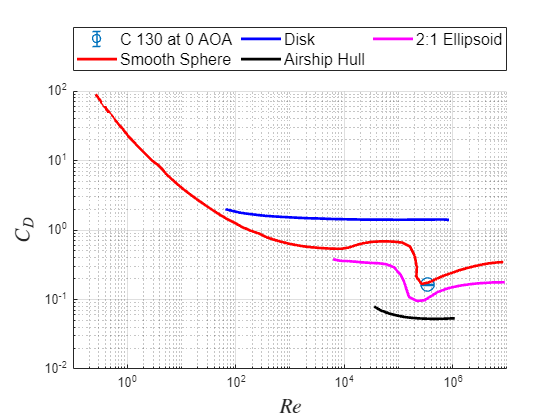

%START PLOTTING STUFF:

% Define variables (assuming these are your calculated values)
angles = [-3,0,3,6,9,12];
Cd_values = [Cd_neg3,Cd_0,Cd_3,Cd_6,Cd_9,Cd_12];
Cl_values = [Cl_neg3,Cl_0,Cl_3,Cl_6,Cl_9,Cl_12];
Cd_values_error = [Cd_neg3_error,Cd_0_error,Cd_3_error,Cd_6_error,Cd_9_error,Cd_12_error];
Cl_values_error = [Cl_neg3_error,Cl_0_error,Cl_3_error,Cl_6_error,Cl_9_error,Cl_12_error];

% Load additional data
load CdvsReData

figure;
hold on;
errorbar(reynolds, Cd_0, Cd_0_error, 'o', 'MarkerSize', 10, 'LineWidth', 1, 'CapSize', 10, 'DisplayName', 'Error')

hold off;
legend('show')

hold on;

plot(CdvsReSphere(:,1), CdvsReSphere(:,2), '-r', ...
    CdvsReDisk(:,1), CdvsReDisk(:,2), '-b', ...
    CdvsReHull(:,1), CdvsReHull(:,2), '-k', ...
    CdvsReEllipsoid(:,1), CdvsReEllipsoid(:,2), '-m', ...
    'LineWidth', 2);
hold off;

grid on;
xlim([0.1 1e7]);
ylim([0.01 100]);
set(gca, 'XScale', 'log', 'YScale', 'log');
xlabel('$Re$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('$C_D$', 'Interpreter', 'latex', 'FontSize', 16);

% Define legend entries for scatter plot
legend_entries_scatter = {'C 130 at 0 AOA'};

% Define legend entries for line plot
legend_entries_line = {'Smooth Sphere', 'Disk', 'Airship Hull', '2:1 Ellipsoid'};

legend([legend_entries_scatter, legend_entries_line], 'Location', 'NorthOutside', 'NumColumns', 4, 'FontSize', 12)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot Cl vs alpha with error bars
figure;
errorbar(angles, Cl_values, Cl_values_error, 'o-', 'LineWidth', 1.5, 'MarkerSize', 8);
xlabel('Angle of Attack (\alpha)');
ylabel('Coefficient of Lift (CL)');
title('Coefficient of Lift vs Angle of Attack');
grid on;
hold on;

%plot the panel theory onto the Cl
Clw_panel = [-.3943,-0.0067,.3785,.7572,1.1252,1.4784];

DOUBLE CHECK THIS TO SEE IF THIS IS A REAL CONVERSTION:

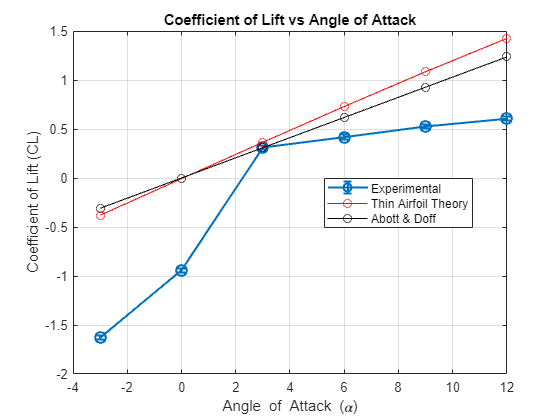

Clw_panel = Clw_panel*2/pi*atan(pi*Aw/2);
Clt_panel = [-.3673,-.004,.3556,.7075,1.04,1.3731];

plot(angles,Clw_panel,'o-r')

%Use the Cl i calculated using the abott and van doff method /datcom
Cla = .103;
plot(angles,Cla*angles,'o-k')

legend('Experimental','Thin Airfoil Theory','Abott & Doff','Location', 'Best');

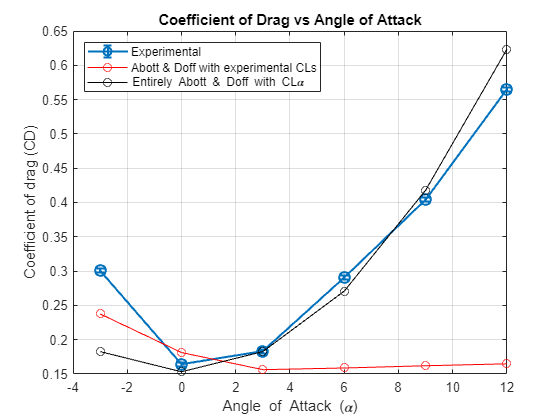




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot Cd vs alpha with error bars
figure;
errorbar(angles, Cd_values, Cd_values_error, 'o-', 'LineWidth', 1.5, 'MarkerSize', 8);
xlabel('Angle of Attack (\alpha)');
ylabel('Coefficient of drag (CD)');
title('Coefficient of Drag vs Angle of Attack');
grid on;
hold on;
%plot the Cd vs alpha for the stability approach
Cd_induced = 0.153246;

%calculate drag polar variables
Cd_total = Cd_induced + (Cl_values.^2)./(ew*Aw*3.1416); %this uses the abott real measured cl's
Cd_total_abott = Cd_induced + (Cla*angles.^2)./(ew*Aw*3.1416); %this uses the abott cl

plot(angles,Cd_total,'o-r')
plot(angles,Cd_total_abott,'o-k')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Note abott and doff estimation of drag based on the calculated Cl is so
%good i think it indicates that the lift data we measured is inaccurate and
%another experiment must be taken place. Because using the theoretical Cla
%it gives an incredible match, which means our actual Cl alpha must be
%garbage

legend('Experimental','Abott & Doff with experimental CLs','Entirely Abott & Doff with CL\alpha','Location', 'NW');

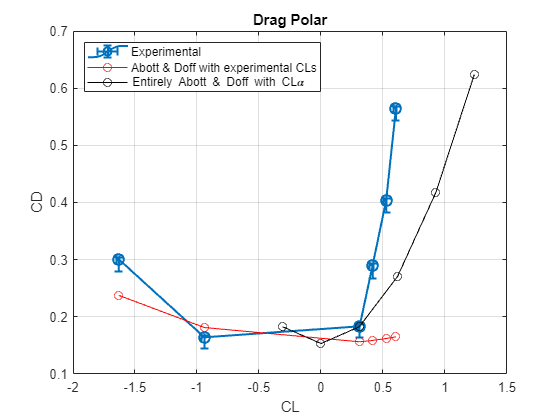


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot the drag polar vs alpha with error bars
figure;
errorbar(Cl_values, Cd_values, Cl_values_error, Cd_values_error,"both", 'o-', 'LineWidth', 1.5, 'MarkerSize', 8);
xlabel('CL');
ylabel('CD');
title('Drag Polar');
grid on;
hold on;
plot(Cl_values,Cd_total,'o-r') %uses the real cls in the drag polar
plot(Cla*angles,Cd_total_abott,'o-k') %uses abott cla to get the Cl in the equation
legend('Experimental','Abott & Doff with experimental CLs','Entirely Abott & Doff with CL\alpha','Location', 'NW');

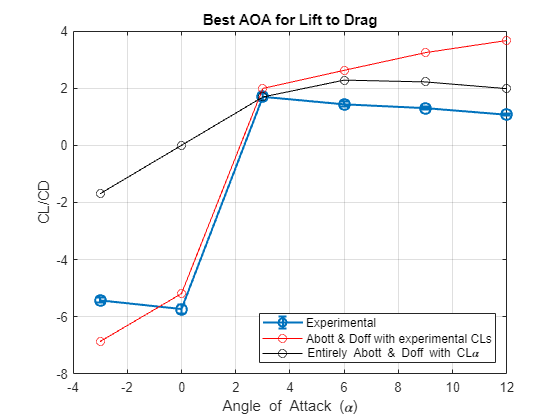


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%plot CL/CD vs alpha
figure
errorbar(angles,Cl_values./Cd_values,Cl_values./Cd_values.*sqrt((Cl_values_error./Cl_values).^2+(Cd_values_error./Cd_values).^2), 'o-', 'LineWidth', 1.5, 'MarkerSize', 8);
xlabel('Angle of Attack (\alpha)');
ylabel('CL/CD');
title('Best AOA for Lift to Drag');
grid on;
hold on;
plot(angles,Cl_values./Cd_total,'o-r') %uses the real cls in the drag polar
plot(angles,(Cla*angles)./Cd_total_abott,'o-k') %uses abott cla to get the Cl in the equation
legend('Experimental','Abott & Doff with experimental CLs','Entirely Abott & Doff with CL\alpha','Location', 'SE');

function read_mat_files(folder_path)
    % List all .mat files in the folder
    files = dir(fullfile(folder_path, '*.mat'));

    % Loop through each file
    for i = 1:numel(files)
        file_path = fullfile(folder_path, files(i).name);
        % Load the data from the file
        data = load(file_path);

        if isfield(data, 'volData')
            datastd=std(data.volData);


            data=(data.volData);
            
            % Get the variable name from the file name (remove .mat extension)
            [~, var_name, ~] = fileparts(files(i).name);
            datastring = append("std",var_name);
            % Assign the data to a variable with the file name
            assignin('caller', var_name, data);
            assignin('caller', datastring, datastd);
        end

        %disp(file_path)
        %disp(data)
        %data = mean(data.volData);

    end
end
